# Image-Based Defect Detection for Manufacturing Inspection

In this project, you will use MATLAB to create a virtual inspection station that processes images of a single part type, produces defect evidence overlays and measurable features, and classifies parts using a pretrained network via transfer learning. You will then evaluate performance and robustness across a repeatable test suite.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Explore and Organize the Image Dataset

- Build a Single-Image Inspection Function

- Train and Integrate an AI Classifier into your Single-Image Inspection Function

- Evaluate Inspection System Performance

- Test and Evaluate System Robustness

## Task 1: Explore and Organize Image Dataset 

###  Setup and Configuration

% You must change the 'root' directory path below to match the exact 
% location of the 'metal_plate' dataset on your local computer before running.

root = "C:\Users\egocr\Documents\GitHub\ImageDefectTeam9\metal_plate";

### How we generated the CSV (Commented out)

This section shows the original logic used to scan the folders, label the data as PASS/FAIL, and generate the 'labels.csv' file. You do NOT need to run this again since the CSV is already saved in the repository, but it is kept here for documentation.

%{
metal_plate Folder Tree
metal_plate
├───ground_truth
│   ├───major_rust
│   ├───scratches
│   └───total_rust
├───test
│   ├───good
│   ├───major_rust
│   ├───scratches
│   └───total_rust
└───train
    └───good
%}
%{
% Define the specific folders and labels

folders = {
    fullfile(root,"train","good"),        "good"
    fullfile(root,"test","good"),         "good"
    fullfile(root,"test","major_rust"),   "major_rust"
    fullfile(root,"test","scratches"),    "scratches"
    fullfile(root,"test","total_rust"),   "total_rust"
    };

% Initialize empty string

filepath = strings(0,1);
defectType = strings(0,1);

% Loop through each folder to find images and assign labels

for i = 1:size(folders,1)
    files = dir(fullfile(folders{i,1}, "*.png"));
    for j = 1:numel(files)
        filepath(end+1,1) = fullfile(files(j).folder, files(j).name);
        defectType(end+1,1) = folders{i,2};
    end
end

% Create pass and fail array

passOrFail = repmat("FAIL", size(defectType));
passOrFail(defectType == "good") = "PASS";

% Combine the three arrays into the labels.csv 

datatable = table(filepath, defectType, passOrFail);
writetable(datatable, fullfile(root, "labels.csv"));

%}

### Datastore 

This section reads the pre-generated CSV and builds the imageDatastore.

% Load the CSV into a table

datatable = readtable(fullfile(root,"labels.csv"), ...
    'Delimiter', ',', ...
    'TextType', 'string', ...
    'VariableNamingRule', 'preserve');

% Create a Datastore with labels

datastore = imageDatastore(datatable.filepath);
datastore.Labels = categorical(datatable.defectType);

## Task 2: Build a Single-Image Inspection Function

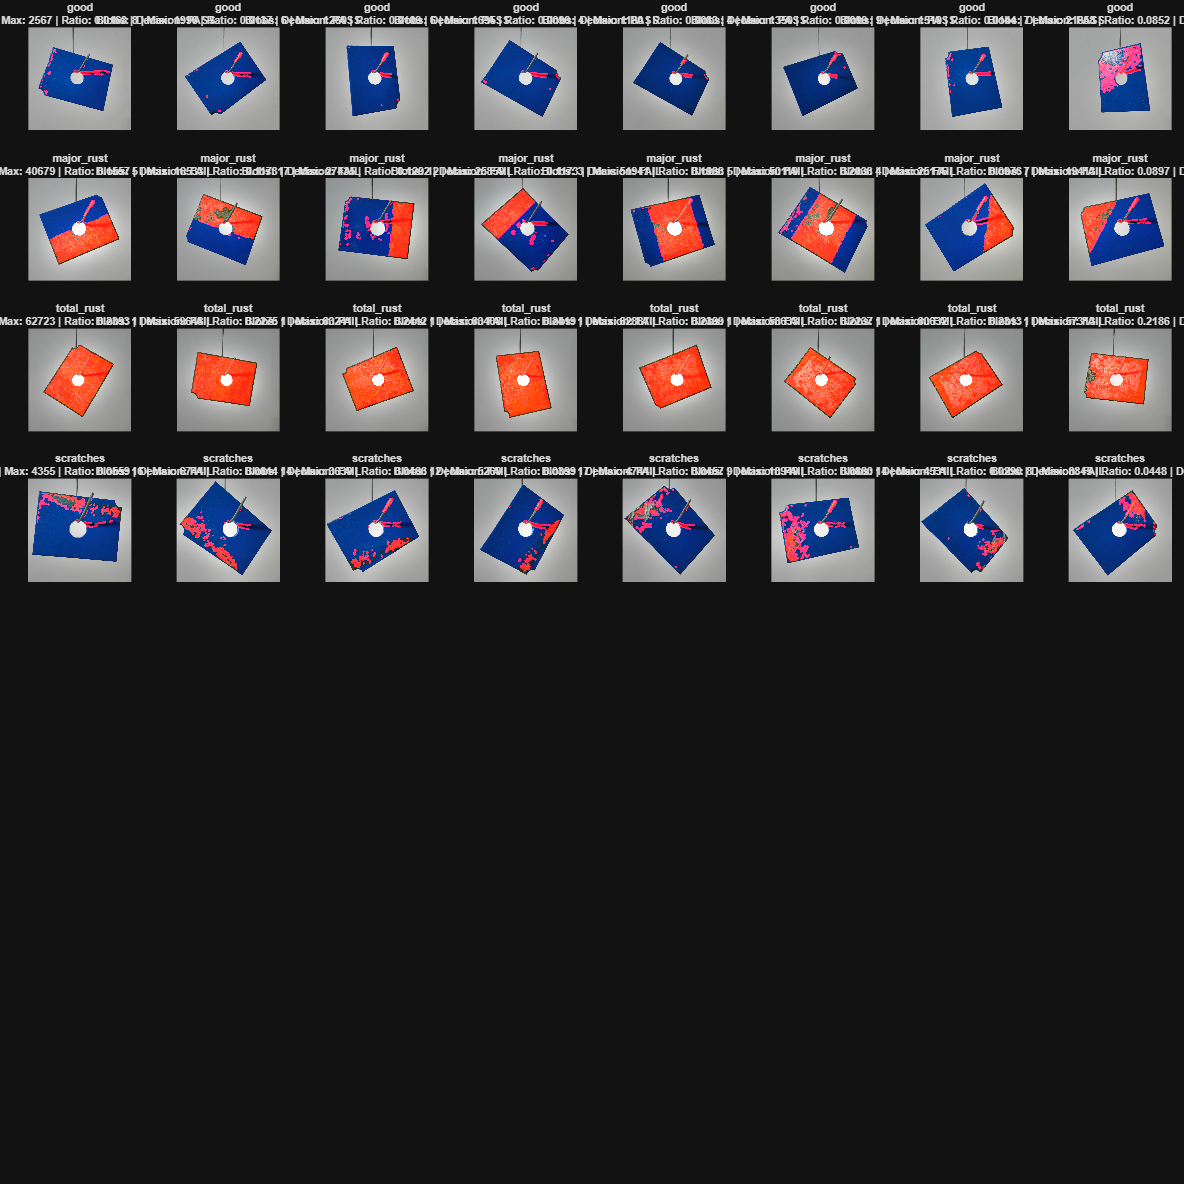

defectCategories  = ["good", "major_rust", "total_rust", "scratches"];

% Create a grid
figure('Name', 'Pipeline Overlay Results', 'Position', [100, 100, 1500, 1500]);
tiledlayout(8, 8, 'TileSpacing', 'compact', 'Padding', 'none');

for c = 1:length(defectCategories)
    
    currentLabel = defectCategories(c);
    
    idx = find(datatable.defectType == currentLabel, 8);
    
    for i = 1:length(idx)
        
        nexttile; 
        
        I = imread(datatable.filepath(idx(i)));
        
        [rgb, gray] = standardizeImage(I, [512 512]);
        partMask = segmentPart(rgb);         
        [rgbCorrected, grayCorrected] = correctLighting(rgb, gray);

        [evidenceMask, rustMask, scratchMask] = defectEvidence(rgbCorrected, grayCorrected, partMask);
        
        metrics = extractMetrics(evidenceMask);
        baselineDecision = decideRules(metrics);

        overlay = rgbCorrected;
        redChannel = overlay(:,:,1);
        redChannel(evidenceMask) = 255; 
        overlay(:,:,1) = redChannel;
        
        imshow(overlay);
        
        titleString = sprintf('%s\nBlobs: %d | Max: %d | Ratio: %.4f | Decision: %s', ...
            currentLabel, metrics.numComponents, metrics.maxArea, metrics.areaRatio, baselineDecision); 

        title(titleString, 'Interpreter', 'none', 'FontSize', 8);

    end
end

## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function

### Dataset Preparation

70% Training, 15% Validation, 15% Testing

[trainImds, remainderImds] = splitEachLabel(datastore, 0.7, 'randomized');
[valImds, testImds] = splitEachLabel(remainderImds, 0.5, 'randomized');

### Image Augmentation 

inputSize = [224 224 3];

% Random rotations and reflections
augmenter = imageDataAugmenter( ...
    'RandRotation', [-5 5], ...
    'RandXReflection', true);

augTrain = augmentedImageDatastore(inputSize(1:2), trainImds, ...
    'ColorPreprocessing','gray2rgb', 'DataAugmentation', augmenter);

augVal   = augmentedImageDatastore(inputSize(1:2), valImds,   'ColorPreprocessing','gray2rgb');
augTest  = augmentedImageDatastore(inputSize(1:2), testImds,  'ColorPreprocessing','gray2rgb');

### Transfer Learning Setup

% Load the pre-trained model
net = resnet18;
lgraph = layerGraph(net);

numClasses = numel(defectCategories);  

% Create two new layers
newFC = fullyConnectedLayer(numClasses, 'Name','new_fc', ...
    'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10);
newClassLayer = classificationLayer('Name','new_classoutput');

% Replace old layers
lgraph = replaceLayer(lgraph, 'fc1000', newFC);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', newClassLayer);

### Network Training

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 1e-4, ...
    'MaxEpochs', 5, ...
    'MiniBatchSize', 16, ...
    'ValidationData', augVal, ...
    'ValidationFrequency', 5, ...
    'OutputNetwork','best-validation-loss', ...
    'Verbose', true, ...
    'Plots', 'training-progress');

% Uncomment if you want to train the network again

%trainedNet = trainNetwork(augTrain, lgraph, options);
%save('trainedNet.mat', 'trainedNet');


load('trainedNet.mat', 'trainedNet');



% Used in inspectPart.m
function [aiLabel, aiScores] = classify(net, roiForNet)
    scores = predict(net, roiForNet);
    classNames = net.Layers(end).Classes;
    [aiScores, idx] = max(scores);
    aiLabel = classNames(idx); 
end

## Task 3 Checkpoint: Combine outputs into a hybrid inspection result

% function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecision] = inspectPart(I, net)
% Function in inspectPart.m


## Task 4: Evaluate Inspection System Performance

### Run AI Evaluation

results = runInspectionSuite(testImds, trainedNet);

### Print  Agreement Summary Table

Table showing if task 2 baseline and  task 3 AI prediction agreed, and shows if AI decision was correct.

summary = groupsummary(results, {'agreementTier','trueLabel'}, 'sum', 'AIDecisionIsCorrect')

### Defect Type Confusion Matrix

Confusion matrix of the 4 defect types.

cleanTrueDefect = strrep(results.trueDefectType, '_', ' ');
cleanAIPred = strrep(results.aiLabel, '_', ' ');
figure
confusionchart(categorical(cleanTrueDefect), categorical(cleanAIPred), ...

summary = 4×4 table
    agreementTier    trueLabel    GroupCount    sum_AIDecisionIsCorrect
    _____________    _________    __________    _______________________

    "Agree-FAIL"      "FAIL"          8                    8           
    "Agree-PASS"      "PASS"          6                    6           
    "Unsure"          "FAIL"          2                    1           
    "Unsure"          "PASS"          6                    6           


    'Title', 'AI Defect Type Confusion Matrix', ...
    'RowSummary','row-normalized', 'ColumnSummary','column-normalized')

### Pass/Fail Confusion Matrix

Confusion matrix of the pass or fail.

figure
confusionchart(categorical(results.trueLabel), categorical(results.aiPred), ...
    'Title', 'AI PASS/FAIL Confusion Matrix')

### AI test images all cases

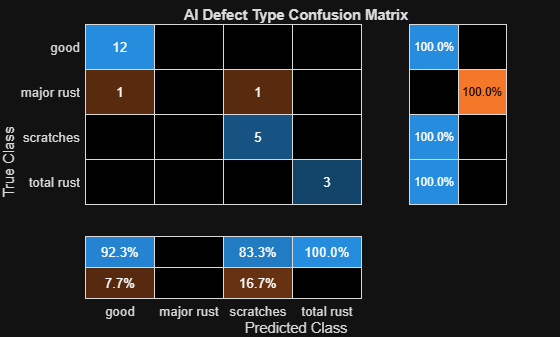

numTotalImages = numel(testImds.Files);

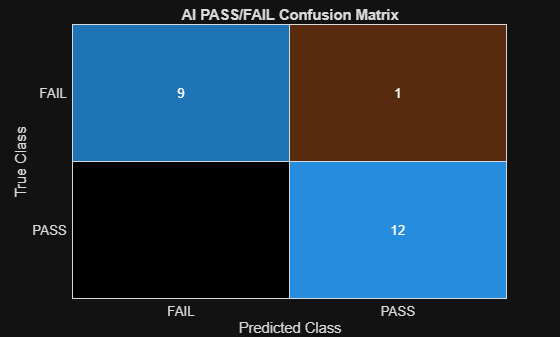


figure('Name', 'Full AI Batch Testing', 'Position', [100, 100, 1200, 1000]);

tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'none');


for i = 1:numTotalImages
    nexttile;
    
    I = readimage(testImds, i);

    actualRealLabel = string(testImds.Labels(i)); 
    
    [finalLabel, confidenceScore, evidenceOverlay, ~, ~] = inspectPart(I, trainedNet);
    finalLabel = string(finalLabel); 
    
    maxConf = max(confidenceScore); 
    
    imshow(evidenceOverlay);
    
    titleStr = sprintf('Actual: %s\nAI Guess: %s (%.1f%%)', ...
        actualRealLabel, finalLabel, maxConf * 100);
    
    % Color the text
    if actualRealLabel == finalLabel
        title(titleStr, 'Interpreter', 'none', 'FontSize', 9, 'Color', '#77AC30'); % Green
    else
        title(titleStr, 'Interpreter', 'none', 'FontSize', 9, 'Color', '#D95319'); % Red
    end
end

### AI failure cases

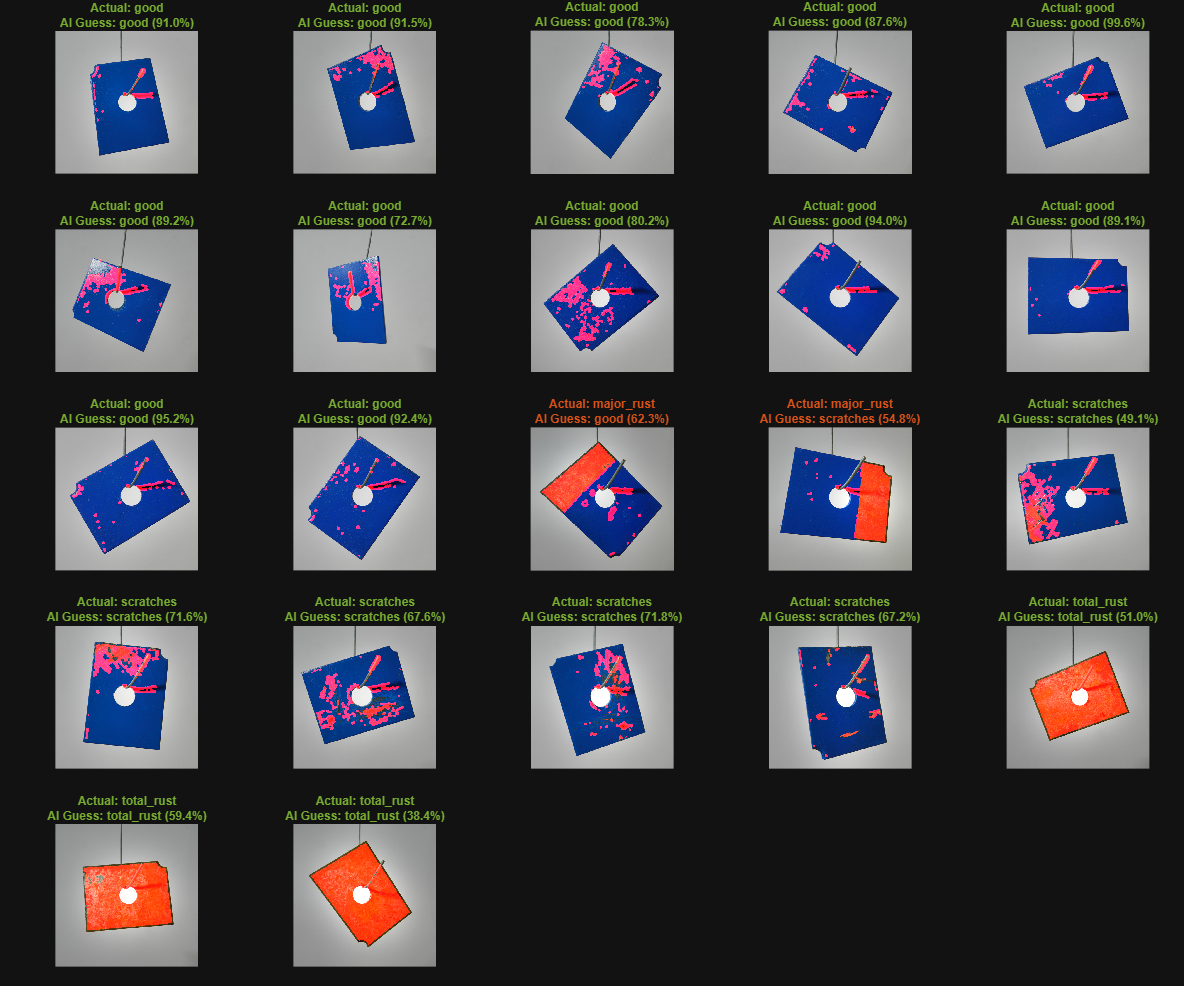

missedIdx = find(results.trueLabel == "FAIL" & results.aiPred == "PASS");

if isempty(missedIdx)
    disp('No defective parts were accidentally passed!')
else
    missedImages = cell(1, numel(missedIdx));

    for k = 1:numel(missedIdx)
        missedImages{k} = imread(results.filepath(missedIdx(k)));
    end

    figure
    montage(missedImages)
    title('CRITICAL MISSES: Defective Parts Predicted as PASS')
end

### Yield & Defect Rates

How many of the metal plates actually passed. (This is AI results)

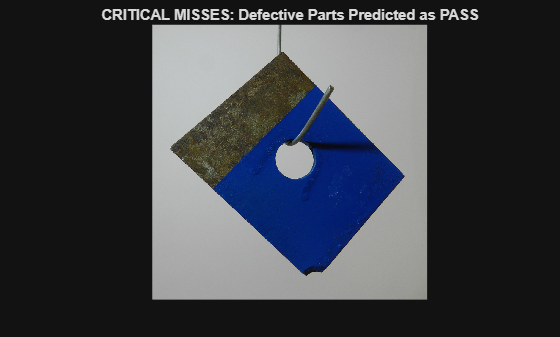

totalParts = height(results);
passCount = sum(results.aiPred == "PASS");
yieldRate = passCount / totalParts * 100;

fprintf('Total parts inspected: %d\n', totalParts);
fprintf('Yield (PASS rate): %.1f%%\n', yieldRate);

fprintf('Defect rate: %.1f%%\n', 100 - yieldRate);

### Defect Type Bar Chart

Specific defect type of the defect metal plates. (This is AI results)

defectBreakdown = groupsummary(results(results.aiPred=="FAIL",:), 'trueDefectType');
disp(defectBreakdown)

figure
bar(categorical(defectBreakdown.trueDefectType), defectBreakdown.GroupCount)
title('Defect Type Bar Chart')

Total parts inspected: 22


ylabel('Count')

Yield (PASS rate): 59.1%


Defect rate: 40.9%


## Task 5: Test and Evaluate System Robustness

### Setting Conditions to Test

conditions = {
    "Clean (baseline)",     []
    "Blur (sigma=2)",       @(I) applyBlur(I, 2)

    trueDefectType    GroupCount
    ______________    __________

     "major_rust"         1     
     "scratches"          5     
     "total_rust"         3     



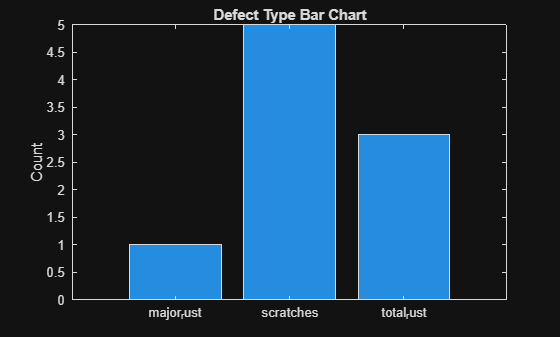

    "Blur (sigma=4)",       @(I) applyBlur(I, 4)
    "Noise (gaussian)",     @(I) applyNoise(I, 'gaussian', 0.01)
    "Noise (salt&pepper)",  @(I) applyNoise(I, 'salt & pepper', 0.05)
    "Low contrast",         @(I) applyContrast(I, 2.5)
    "High contrast",        @(I) applyContrast(I, 0.4)

    };



### Test Accuracy, FalseRejectRate and MissedDefectRate for Each Condition

robustnessResults = table();
for c = 1:size(conditions,1)
    label = conditions{c,1};
    fcn = conditions{c,2};
    r = runInspectionSuite(testImds, trainedNet, fcn);

    acc = mean(r.AIDecisionIsCorrect);
    falseReject  = sum(r.trueLabel=="PASS" & r.aiPred=="FAIL") / sum(r.trueLabel=="PASS");
    missedDefect = sum(r.trueLabel=="FAIL" & r.aiPred=="PASS") / sum(r.trueLabel=="FAIL");

    robustnessResults = [robustnessResults; ...
        table(string(label), acc, falseReject, missedDefect, ...
        'VariableNames', {'Condition','Accuracy','FalseRejectRate','MissedDefectRate'})];
end

disp(robustnessResults)

### Bar Graph of Accuracy

figure
bar(categorical(robustnessResults.Condition), robustnessResults.Accuracy)
title('Accuracy Across Different Simulated Conditions')
ylabel('Accuracy')
xtickangle(30)

### Example of Each Distortion

index = [1, 6, 12, 18];

figure('Name', 'Distortion Preview Grid', 'Position', [100, 100, 1400, 1900]);
tiledlayout(size(conditions,1), numel(index), 'TileSpacing', 'none', 'Padding', 'none');

          Condition          Accuracy    FalseRejectRate    MissedDefectRate
    _____________________    ________    _______________    ________________

    "Clean (baseline)"       0.95455               0              0.1       
    "Blur (sigma=2)"         0.81818               0              0.4       
    "Blur (sigma=4)"         0.68182               0              0.7       
    "Noise (gaussian)"       0.95455               0              0.1       
    "Noise (salt&pepper)"    0.86364         0.16667              0.1       
    "Low contrast"           0.72727        0.083333              0.5       
    "High contrast"          0.86364        0.083333              0.2       



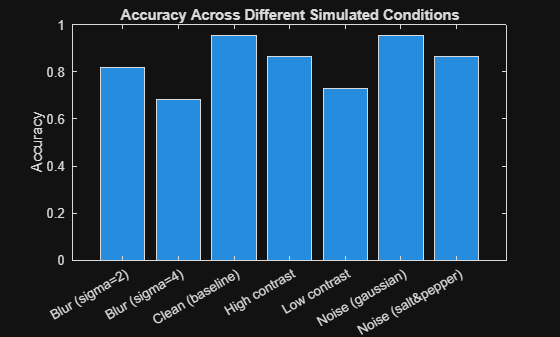


for c = 1:size(conditions,1)
    fcn = conditions{c,2};
    for k = 1:numel(index)
        nexttile;
        I = readimage(testImds, index(k));

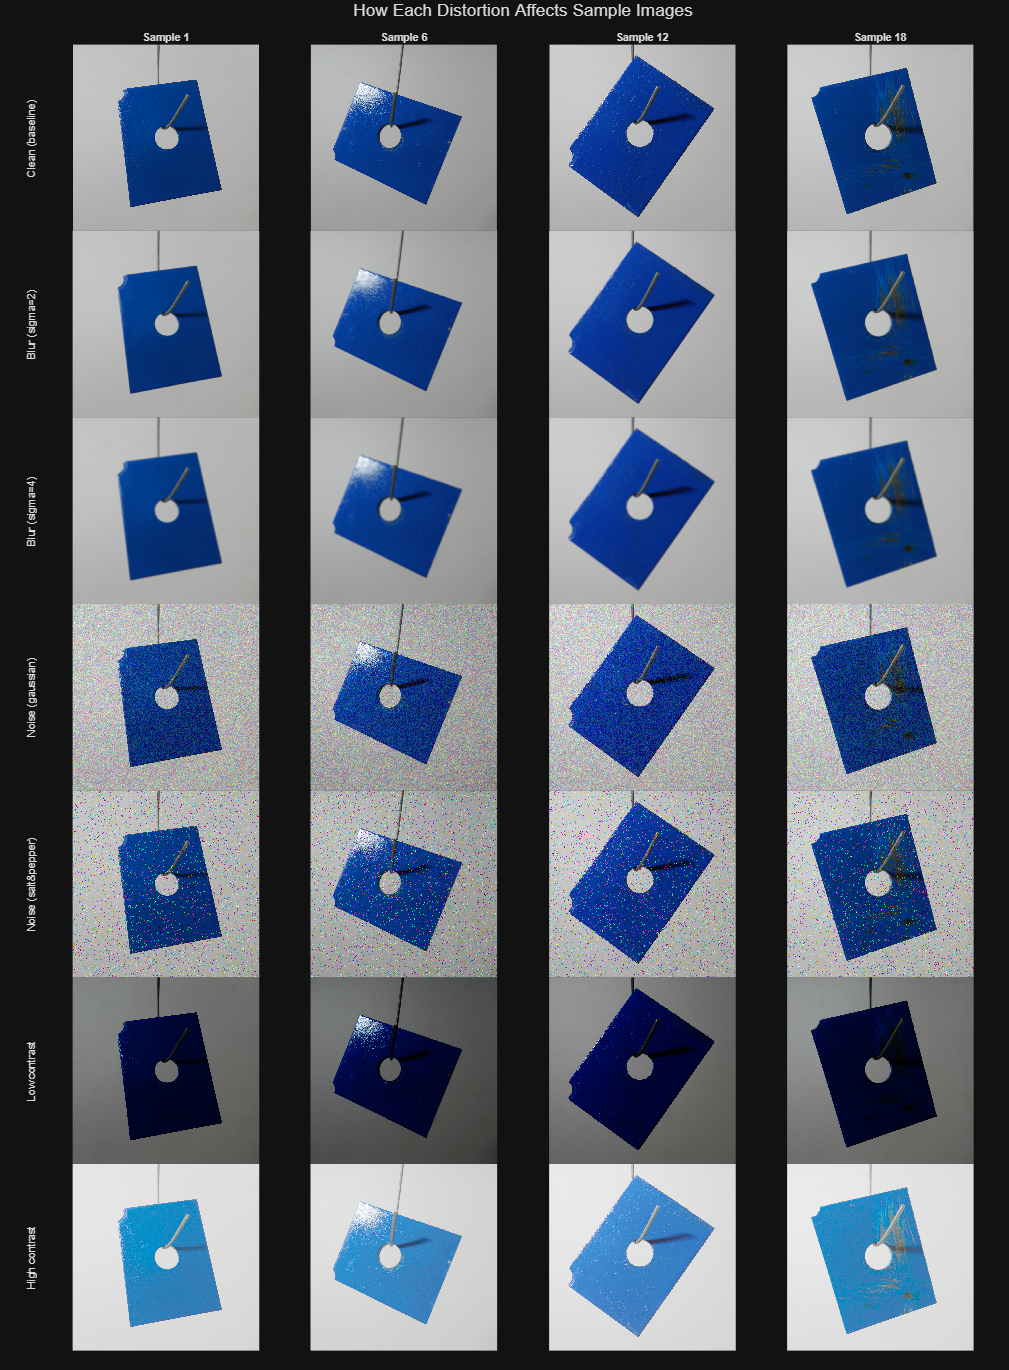

        if ~isempty(fcn)
            I = fcn(I);
        end
        imshow(I);
        if k == 1
            ylabel(conditions{c,1}, 'FontSize', 8, 'Interpreter', 'none');
        end
        if c == 1
            title(sprintf('Sample %d', index(k)), 'FontSize', 8);
        end
    end
end
sgtitle('How Each Distortion Affects Sample Images')

## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?